This is a livescript to check the z2r transform issue. 

z2r=load('C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\WB_anticip_phase_diff_summary.mat');
noz2r=load('C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\WB_anticip_phase_diff_summary_corr_NOz2rconv.mat');


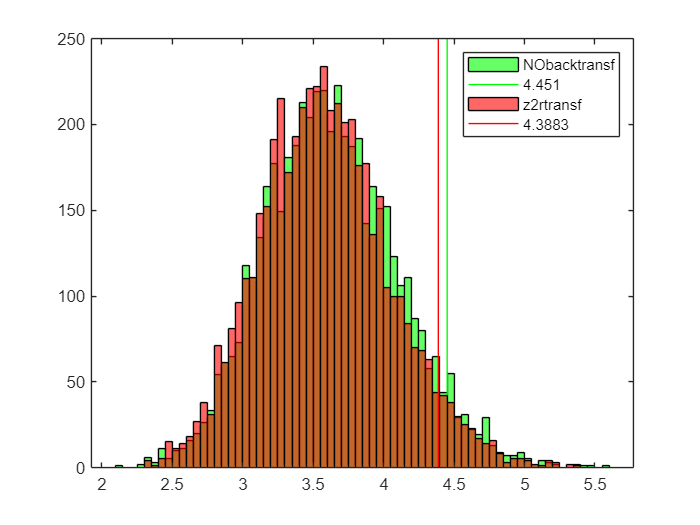

noz2rthrs=prctile(noz2r.summaryy.permres.r.rnd.zmaxvals,95);
z2rthrs=prctile(z2r.summaryy.permres.r.rnd.zmaxvals,95);
figure()
histogram(noz2r.summaryy.permres.r.rnd.zmaxvals,'FaceColor', 'green','BinWidth',.05)
vline(noz2rthrs,'color','green')
hold on
histogram(z2r.summaryy.permres.r.rnd.zmaxvals,'FaceColor', 'red','BinWidth',.05)
vline(z2rthrs,'color','red')
legend(["NObacktransf",noz2rthrs,"z2rtransf",z2rthrs])

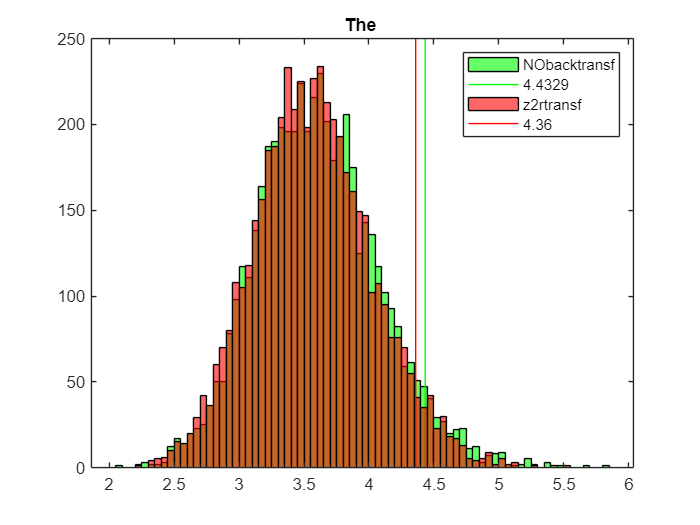

noz2rthrs=prctile(-noz2r.summaryy.permres.r.rnd.zminvals,95);
z2thrs=prctile(-z2r.summaryy.permres.r.rnd.zminvals,95);
figure()
histogram(-noz2r.summaryy.permres.r.rnd.zminvals,'FaceColor', 'green','BinWidth',.05)
vline(prctile(noz2rthrs,95),'color','green')
hold on


histogram(-z2r.summaryy.permres.r.rnd.zminvals,'FaceColor', 'red','BinWidth',.05)


vline(z2thrs,'color','red')
legend([["NObacktransf",noz2rthrs],"z2rtransf",z2thrs])
title("The ")